# Mobile Robot Simulation - Exploration and Cleaning Task

This live script demonstrates the simulation of a mobile robot performing area exploration and cleaning using triangular cones as markers to define boundaries. The robot uses a control system to navigate, avoid obstacles, and map its environment.

## Initialization and Setup

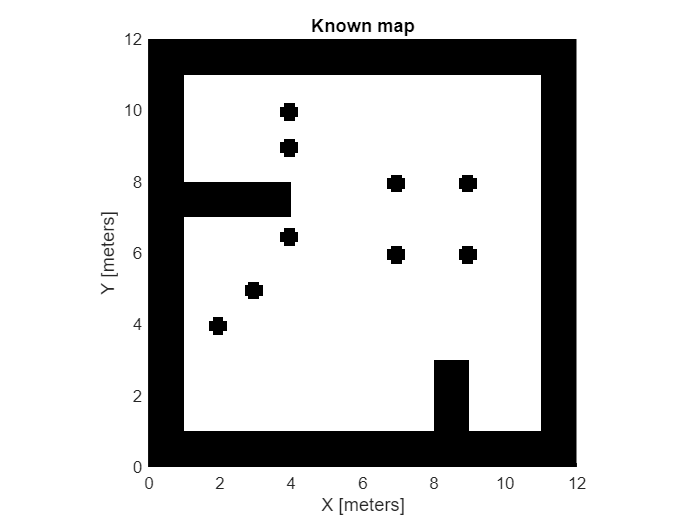

clear
clear TASPpathPlanning
addpath(fullfile(pwd, 'functions'));
%% Robot system parameters
% Sensor parameters
cameraRange = 6; %meters
cameraFov = 60; % degrees
lidarRange = 8; % meters

%% Simulation environment setup
% Original map
load('Map/knownMap2.mat');
expansionMatrix = ones(10,10);
expandedMatrix = kron(customMap, expansionMatrix);
mapResolution = 10; % Cells per meter
knownMap = occupancyMap(expandedMatrix, mapResolution);
% Cones map
coneMapLayer = occupancyMap(knownMap.GridSize(2)/mapResolution,knownMap.GridSize(1)/mapResolution, mapResolution);
setOccupancy(coneMapLayer, ones(coneMapLayer.DataSize) * 0);
coneLocations = [2 4; 3 5; 4 6.5; 4 9; 4 10; 7 6; 7 8; 9 6; 9 8];
conePvalues = ones(length(coneLocations), 1);
inflationRadius = 0.2;
setOccupancy(coneMapLayer, coneLocations, conePvalues);
inflate(coneMapLayer,inflationRadius);
coneLines = {};
%Combine the inflated cone layer with the original map
getOccupancy(knownMap);
getOccupancy(coneMapLayer);
combinedMap = (getOccupancy(knownMap)>0.5) | (getOccupancy(coneMapLayer)>0.5);
setOccupancy(knownMap, combinedMap);
% Define the map
figure('Name','knownMap');
hold on;
show(knownMap);
title('Known map');
hold off;

% Unknown map
figure('Name','unknownMap');
[mapdimx, mapdimy] = size(expandedMatrix);
unknownMap = occupancyMap(mapdimx/mapResolution, mapdimy/mapResolution, mapResolution);

## Robot Motion and Control

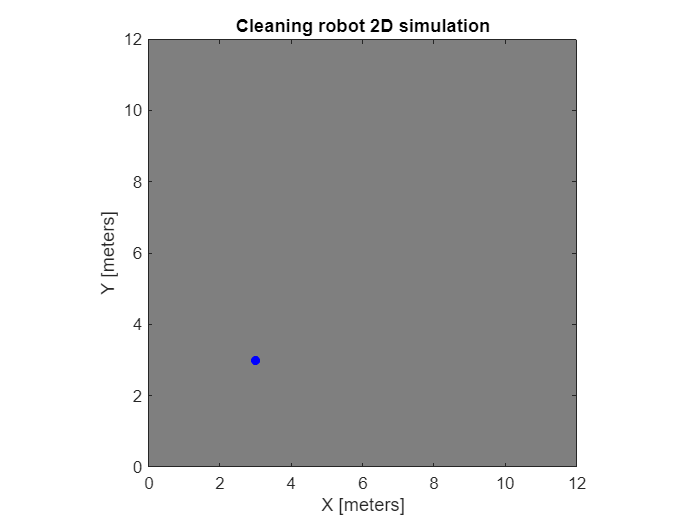

% Set parameters for robot motion control
linearVelocityGain = 2;  % Gain for linear velocity
angularVelocityGain = 3; % Gain for angular velocity
goalTolerance = 0.3;       % Distance tolerance to consider the robot at a goal point
% Initial robot state
startPos = [3 3 pi/2];
robot.position = startPos(1:2);
robot.orientation = startPos(3); % radians
robot.trajectory = [robot.position];
% Control parameters
timeStep = 0.2;  % Time step for motion control (seconds)
taspCellSize = 1; % BTP cell size, meter

% Figure setup
figure;
show(unknownMap);
title('Cleaning robot 2D simulation');
hold on;

% Draw the robot's start position
plot(robot.position(1),robot.position(2), 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'b');


% Scan map, update map
updateUnknownMapWithScan(robot, knownMap, unknownMap);

Unrecognized function or variable 'updateUnknownMapWithScan'.

% Get new goal
TASPgoal = TASPpathPlanning(startPos, unknownMap, taspCellSize);
PlotTASPgoal = plot(TASPgoal(1), TASPgoal(2), 'ro', 'MarkerSize', 4);

% Plan the path with Astar
plannedPath = planPath(robot, TASPgoal , unknownMap);

while ~isempty(TASPgoal)  
    % Robot motion control
    robot = moveAlongPlannedPath(robot, plannedPath, linearVelocityGain, angularVelocityGain, goalTolerance, timeStep);

    % Scan map, update map
    updateUnknownMapWithScan(robot, knownMap, unknownMap);
    % Detect and update cones
    [coneLocations, coneLines] = detectAndUpdateCones(coneLocations, robot, coneLines, knownMap);

    % Get new goal
    TASPgoal = TASPpathPlanning(startPos, unknownMap, taspCellSize);
    delete(PlotTASPgoal);
    PlotTASPgoal = plot(TASPgoal(1), TASPgoal(2), 'ro', 'MarkerSize', 4);
    % Plan the path with Astar
    plannedPath = planPath(robot, TASPgoal , unknownMap);

    drawnow;
end
